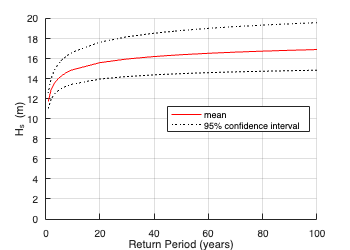

clearvars; close all
cd /Users/vincent/Downloads/ReturnPeriodCalc % Change to your path

load('TS.mat')

% ----- Define Parameters

WinterMonths = [10,11,12,1,2,3,4]; % October to April
TempRes = 1; % 1 hour
MSD = 6; % Minimum Storm Duration, 6 hours
THperc = 95; % Percentage of Storm Treshold
CF_alpha = 0.05; % 95% Confidence interval


% ----- Main 

[R,HRP,Lower_RP,Upper_RP,icStorm,info,TT_POT,ST,ID,IT] = RPcalc(TS,WinterMonths,TempRes,MSD,THperc,CF_alpha);

% ----- Plot

f1 = figure(1);
set(f1,'position',[10,10,350,250],'Color','w');

plot(R,HRP,"-r","DisplayName","mean");
hold on
plot(R,Upper_RP,":k","DisplayName",[num2str((1-CF_alpha)*100),'% confidence interval']);
plot(R,Lower_RP,":k","HandleVisibility","off");

grid('on');
box('off')
ylim([0,20]);
xlim([0,100]);
ylabel('H_{s} (m)');
xlabel('Return Period (years)');
legend('Location','east')